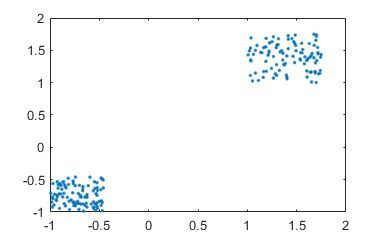

o1 = rand(100,2)*0.75 + ones(100,2);
o2 = rand(100,2)*0.55 - ones(100,2);
O =[o1;o2];
plot(O(:,1),O(:,2),'.')

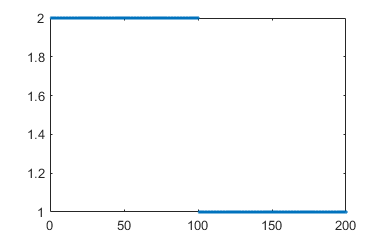

L = kmeans(O,2);
%% la etiqueta no te res a veure amb els valors, nomes es un identificador del grup al q pertanyen
plot(L(:,1),'.')


[L G] = kmeans(O,2) %%G son els centroides??

L =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


G =     1.4141    1.3951
   -0.7153   -0.7471



plot(O(L==1,1),O(L==1,2),'r.'); hold

Current plot held


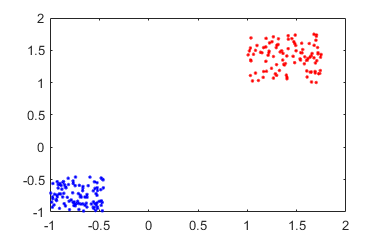

plot(O(L==2,1),O(L==2,2),'b.'); hold off

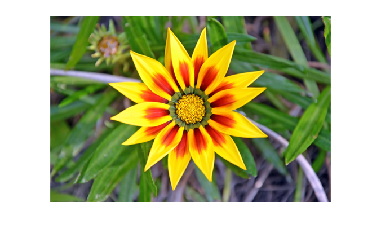

I = imread('flor.png');
I = imresize(I,0.2);
imshow(I);

%rec = getrect();

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

O = double([R(:),G(:),B(:)]);
[L,centroids] = kmeans(O,16)

L =     13
    12
    12
    13
    12
    13
    13
    13
    13
    13


centroids =    77.6974  115.9986   67.1522
  252.0177  221.5620    9.0776
  105.0457  139.7724   44.8369
  188.9312  179.9028  217.3211
  245.9151   89.7097   22.6479
   36.8512   37.0557   37.8001
  116.1296  142.7587   92.2765
  209.7767   40.1618   11.0115
   98.0750  100.1600  102.9558
  234.9404  165.9388    8.2207


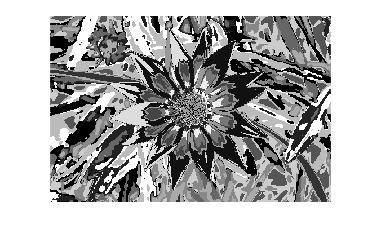

%plot(L(:,1),'.')
[f,c,p] = size(I);
S = reshape(L,[f,c]);
imshow(S,[])

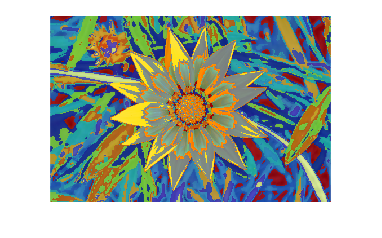

L = labeloverlay(I,S);
imshow(L,[])

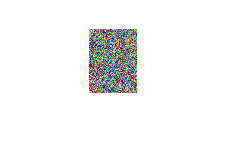

RGB  = rand(64, 48, 3);  % RGB Image
R    = RGB(:, :, 1);
G    = RGB(:, :, 2);
B    = RGB(:, :, 3);
IMG1 = cat(3, G, R, B);
imshow(IMG1)